# Measuring Orientation from a Planar Section

Chapter 3 discusses how orientation is measured from polished cross-sections of molded parts.  Glass and carbon fibers are circular cylinders, so they appear as ellipses on a section plane.  By measuring the major and minor axes of the ellipse, one can determine the angles $\theta$ and $\phi$ relative to the section plane.  

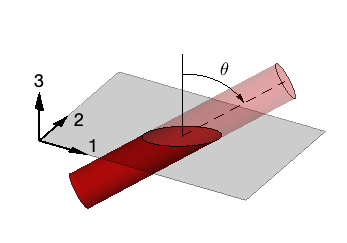   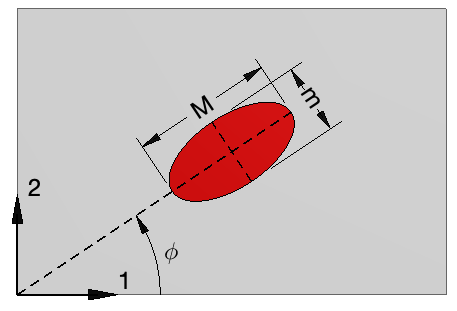

However, the fibers that appear on a section plane are a biased sample.  Fibers whose axes are more perpendicular to the plane ($\theta$ close to 0) are more likely to appear, while fibers whose axes are more parallel to the plane ($\theta$ close to $\pi/2$) are less likely to appear.

To correct for this, we use a $\theta$-dependent weighting factor $F_k$ for each fiber when computing averages from the section data.  For the orientation tensor component $A_{ij}$ this is


$$A_{ij} = \frac{\sum_{k=1}^N \; (p_i p_j)_k F_k}{\sum_{k=1}^N \;  F_k}$$


The most commonly used weighting function is due to Bay:


$$    F_k = \left\{  \begin{array}{lcc}
                              1 / \cos \, \theta_k   & \text{for}  & 0 \le \theta_k \le \theta_c  \\
                              1/  \cos \, \theta_c    & \text{for}  &  \theta_c < \theta \le \pi/2
               \end{array}  \right.$$


Here $\theta_c$ is given by $\cos \theta_c = d_f / \ell$, with $d_f$ the fiber diameter and $\ell$ the fiber length.  This gives reasonable weighting factors for fibers with $\theta$ close to $\pi/2$.  

Example 3.1.1 illustrates the use of this approach for a simple data set.  The section plane looks like this:

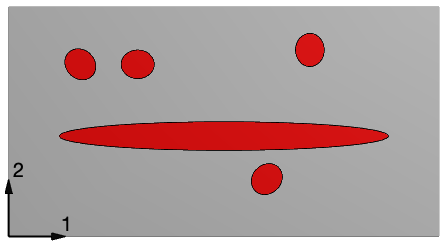

The four nearly-circular fibers have  = 30 degrees and $\phi$ values of 0, 45, 90 and 135 degrees.  The elongated fiber has $\theta$ = 85 degrees and $\phi$ = 0 degrees.

To calculate the orientation tensor, we use the function `thetaphi2A`:

theta = deg2rad([30, 30, 30,  30, 85]);  % Given
phi   = deg2rad([0,  45, 90, 135,  0]);  % Given
fprintf('Orientation tensor for this section:\n')

Orientation tensor for this section:


A = thetaphi2A(theta, phi)

A =     0.7434    0.0000    0.1369
    0.0000    0.0359    0.0750
    0.1369    0.0750    0.2207


This matches the answer in the book, Eqn. (3.12), except for the $A_{13} $ component (and $A_{31}$).  Here we have $A_{13}$ = 0.1369, while the book has $A_{13}$ = 0.093.  This occurs because `thetaphi2A` accounts for ambiguity in the value of $\phi$

The example calculation in the book treats $\theta$ and $\phi$ as being known exactly for each fiber, so the off-diagonal components of $\mathbf{A}$ are known exactly.  In practice, $\phi$ could be replaced by $\phi + \pi$ and the ellipse on the section plane would look the same.  This means that $A_{13} = A_{31}$ and $A_{23} = A_{32}$ cannot be determined exactly using only the $\theta$ and $\phi$ values from ellipses on the section plane.  The diagonal components and $A_{12} = A_{21}$ are determined without ambiguity.  (This assumes that the 1-2 plane is the section plane).  

To address this, `thetaphi2A` computes the upper bounds of the ambiguous components.  The lower bounds are found by changing the sign on these components.  In this case the true value of $A_{13}$ = 0.093 is less than the upper bound, while the true value of $A_{23}$ happens to equal the upper bound.  